close all;
clear all;
clc;

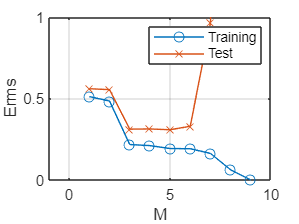

rng(19);

Ntrain = 10;
Xtrain = rand(Ntrain,1);
epsilontrain = normrnd(0,0.3,Ntrain,1);
ttrain = sin(2*pi*Xtrain)+epsilontrain;

Ntest = 100;
Xtest = rand(Ntest,1);
epsilontest = normrnd(0,0.3,Ntest,1);
ttest = sin(2*pi*Xtest)+epsilontest;

phitrain = ones(10,1);
phitest = ones(100,1);
Ermst = [];
Ermstr = [];

for a=1:9
    phitrain = [Xtrain.^a phitrain];
    A = pinv(phitrain)*ttrain;
    B = phitrain*A;
    etrain = norm(B-ttrain,2).^2;
    e = etrain/Ntrain;
    Ermst = [Ermst sqrt(e)];
    
    phitest = [Xtest.^a phitest];
    B2 = phitest*A;
    etest = norm(B2-ttest,2).^2;
    e2 = etest/Ntest;
    Ermstr = [Ermstr sqrt(e2)];
end

%plot
figure(1);
plot (1:9, Ermst, '-o');
hold on;
grid on;
plot (1:9, Ermstr, '-x');
ylim([0 1]);
xlim([-1 10]);
xlabel('M');
ylabel('Erms');
legend('Training','Test');

Ntrain1 = 10;
Xtrain1 = rand(Ntrain1,1);
epsilontrain1 = normrnd(0,0.3,Ntrain1,1);
ttrain1 = sin(2*pi*Xtrain1)+epsilontrain1;

Ntest1 = 100;
Xtest1 = rand(Ntest1,1);
epsilontest1 = normrnd(0,0.3,Ntest1,1);
ttest1 = sin(2*pi*Xtest1)+epsilontest1;

for b=0:9
    phitrain1 += Xtrain1.^b;
    A1 = pinv(phitrain1)*ttrain1;
    B1 = phitrain1*A1;
    etrain1 = norm(B-ttrain1,2).^2;
    er = etrain1/Ntrain1;
    Ermst2 = sqrt(er);
    
    phitest1 += Xtest1.^b;
    B12 = phitest1*A1;
    etest1 = norm(B12-ttest1,2).^2;
    er2 = etest1/Ntest1;
    Ermstr2 = sqrt(er2);
end

Unrecognized function or variable 'phitrain1'.


%plot
figure(2);
plot (0:9, Ermst2, '-o');
hold on;
grid on;
plot (0:9, Ermstr2, '-x');
ylim([0 1]);
xlim([-1 10]);
xlabel('M');
ylabel('Erms');
legend('Training','Test');